# Calculate Optical Properties using Bayesian Inverse Techniques

## Read AVIRIS data and Create Input Settings for Bayesian Solution

% Load AVIRIS data structure
clear variables

folderName = './AVIRIS_Classic_data/8_20_2018/f180820t01p00r09rdn_e/';

fileName = 'f180820t01p00r09rdn_e';

aviris = readAVIRIS_classic(folderName,fileName);


% now lets load the bayesian function inputs
model_prior = 'gaussian';


inputs = create_bayes_inputs(model_prior);


## Read MODIS data and Create Input Settings for Bayesian Solution

% Load modis data and create input structure
clear variables

folderName = '/Users/andrewbuggee/Documents/MATLAB/CU Boulder/Hyperspectral_Cloud_Retrievals/MODIS_Cloud_Retrieval/MODIS_data/2021_08_25/';

L1B_500m_fileName = 'MOD02HKM.A2021237.1920.006.2021238072711.hdf';

L1B_1km_fileName = 'MOD021KM.A2021237.1920.006.2021238072711.hdf';

geoFileName = 'MOD03.A2021237.1920.006.2021238012056.hdf';

L2_fileName = 'MOD06_L2.A2021237.1920.061.2021238075516.hdf';

modis = retrieveMODIS_data(L1B_500m_fileName, geoFileName,L2_fileName);

data_inputs = load([folderName,'uvspec_CALCS_23-Nov-2021.mat'],'R','pixels2use','inputs','truthTable');

% now lets load the bayesian function inputs
model_prior = 'gaussian';


inputs = create_bayes_inputs(model_prior);

inputs = create_measurement_prior(inputs,modis,data_inputs);



## Create Jacobian Matrix

% Lets check to see if a look up table has been computed

% -------------------------------------------------------------
% -- For now, load in look-up tables --
% -- later on, make a smart code to search for lookup tables --
% -------------------------------------------------------------


% for now, grabs jacobian for a single pixel 
[K] = create_Jacobian_from_lookup_table(inputs,data_inputs,folderName);



## Calculate Retrieval Parameters

% Lets calculate the posterior pdf and the posterior covariance

if strcmp(model_prior,'gaussian') == true && strcmp(measurement_prior,'gaussian')==true
    
    retrieval = calc_retrieval_likelihood(inputs,data_inputs,modis,K);
    
    %S_posterior = compute_gaussian_posterior_likelihood(inputs,data_inputs,K,modis);
    
else
    error('Dont know how to compute posterior covariance for non-gaussian pdfs')
    
end

## Plot retrieved values versus Modis Estimates

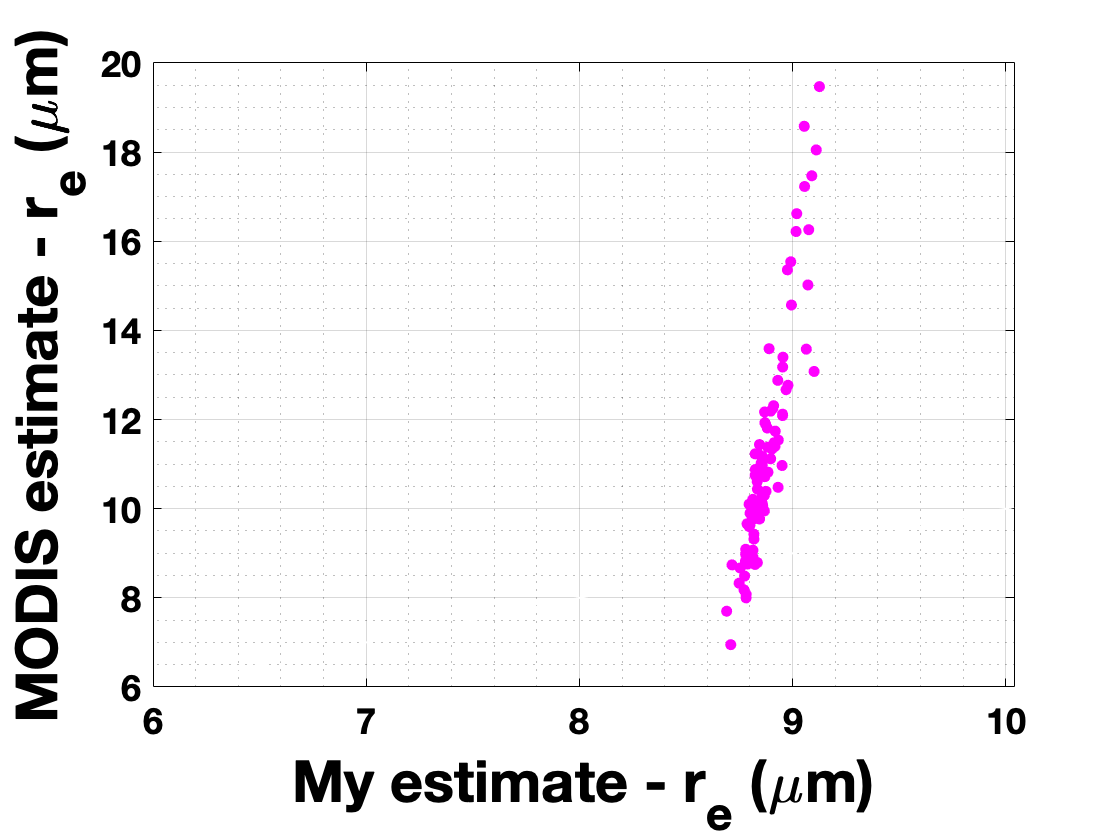


% ---- Plot effective radius first -----

% find the minimum and maximum values to create a y=x line

min_re_est = min(retrieval(1,:));
min_re_modis = min(data_inputs.truthTable.modisR17);

max_re_est = max(retrieval(1,:));
max_re_modis = max(data_inputs.truthTable.modisR17);

min_global = min([min_re_est,min_re_modis]);

max_global = min([max_re_est,max_re_modis]);

x = linspace((0.9 * min_global),(1.1*max_global),150);


figure; plot(x,x,'w-','Linewidth',1)
hold on; grid on; grid minor
plot(retrieval(1,:),data_inputs.truthTable.modisR17,'m.')
xlabel('My estimate - r_{e} (\mum)')
ylabel('MODIS estimate - r_{e} (\mum)') 

## Calculate the Posterior Distribution

% here is where I will talk about averaging kernels

## Calculate Information Content

% here is where I will talk about averaging kernels

## Calculate Degrees of Freedom for Signal

% here is where I will talk about averaging kernels

## Optimize Channel Selection Based on Information Content

% here is where I will talk about averaging kernels

## Optimize Channel Selection Based on Degrees of Freedom for Signal

% here is where I will talk about averaging kernels

## Calculate Averaging Kernels

% here is where I will talk about averaging kernels

## Create Input Structure for Bayes Functions

% create the input structure for the bayesian inverse functions


function bayes_inputs = create_bayes_inputs(model_prior)

bayes_inputs.measurement.prior = 'gaussian';


% define the number of model parameters to solve for
bayes_inputs.num_model_parameters = 2;

% -------------------------------------------
% --- Stuff for the Model Parameter Prior ---
% -------------------------------------------

if strcmp(model_prior,'custom')

    % lets create the variance and mean for each model parameter
    bayes_inputs.model.variance = [4,10]; % variance for the effective radius (microns squared) and optical thickness respectively
    bayes_inputs.model.mean = [10,15]; % expected values for the effective radius (microns) and the optical depth
    bayes_inputs.model.covaraince = diag(bayes_inputs.prior.variance);

    error('mvnpdf is not properly set up yet!')

    bayes_inputs.model.prior = mvnpdf(bayes_inputs.model.mean,bayes_inputs.model.covaraince);



elseif strcmp(model_prior,'Standard_Normal')
    % if the standard normal option is chosen, the code assumes the model
    % parameters take on the standard normal gaussian, where the the
    % expected value for each parameter is 0, and the variance is 1

    bayes_inputs.model.varaince = ones(1,bayes_inputs.num_model_parameters);
    bayes_inputs.model.mean = zeros(1,bayes_inputs.num_model_parameters);

    % create the covaraince matrix of the model parameters
    bayes_inputs.model.covaraince = diag(bayes_inputs.prior.variance);

    error('standard normal option is not properly set up yet!')


elseif strcmp(model_prior,'gaussian')
    % if the 'gaussian' option is chosen, a multivariate gaussian pdf with
    % custom variance and mean will be implemented

    % lets create the variance and mean for each model parameter
    bayes_inputs.model.variance = [4,10]; % variance for the effective radius (microns squared) and optical thickness respectively
    bayes_inputs.model.mean = [10,15]; % expected values for the effective radius (microns) and the optical depth
    bayes_inputs.model.covaraince = diag(bayes_inputs.model.variance);


    % since we are assuming the model prior is gaussian, we don't need to
    % keep track of the PDF.

end




end
